# Identificazione in presenza di limitazioni di velocità/posizione massima.

## Giunto 2

consideriamo un robot scara in cui è stato aggiunto un disturbo chirp al secondo giunto

clc;clear all;close all;
model_name='scara0';
load([model_name,'/tests/chirp_experiment_joint2_20250214153620.mat'])
fprintf('Giunto=%d\n',joint_number+1);

Giunto=2


fprintf('Chirp con Ampiezza %f da %f a %f\n',A,f0,f1)

Chirp con Ampiezza 10.000000 da 1.000000 a 500.000000


punto_di_lavoro=mean(joint_position);
fprintf('Punto di lavoro [%f %f]',punto_di_lavoro(1),punto_di_lavoro(2))

Punto di lavoro [0.481462 1.566997]

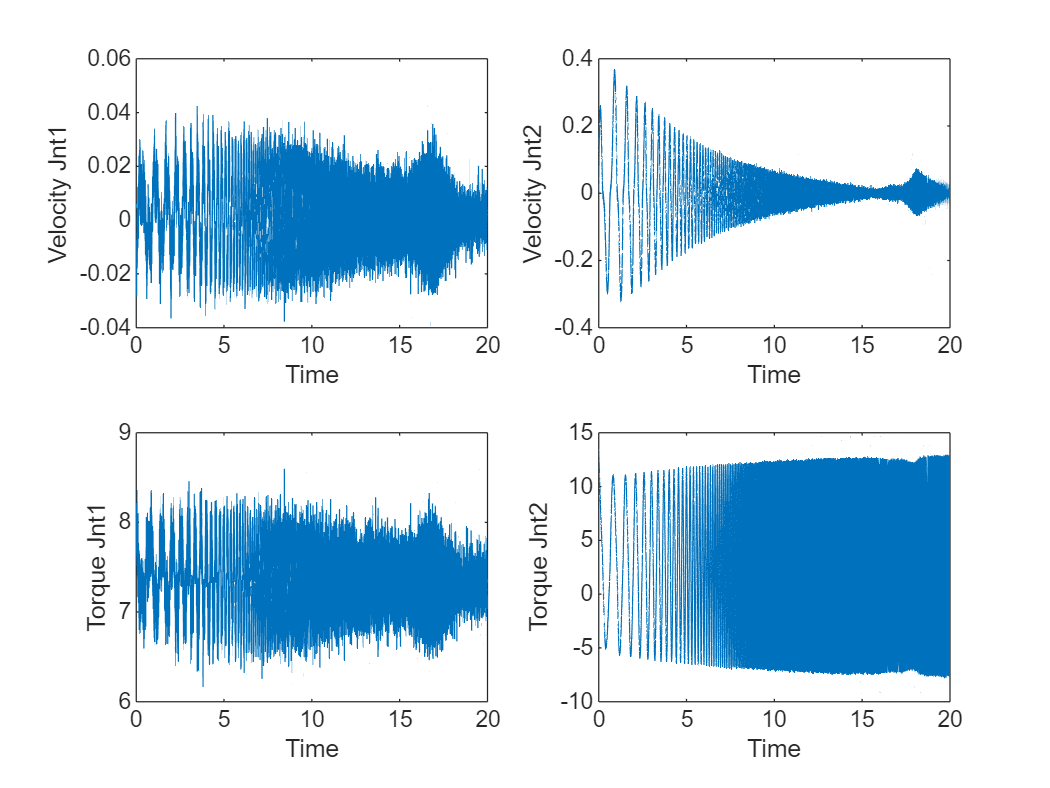

ngiunto=joint_number+1;
Tc=time(2)-time(1);

figure
subplot(2,2,1)
plot(time,joint_velocity(:,1))
ylabel('Velocity Jnt1')
xlabel('Time')
subplot(2,2,3)
plot(time,joint_torque(:,1))
ylabel('Torque Jnt1')
xlabel('Time')
subplot(2,2,2)
plot(time,joint_velocity(:,2))
ylabel('Velocity Jnt2')
xlabel('Time')
subplot(2,2,4)
plot(time,joint_torque(:,2))
ylabel('Torque Jnt2')
xlabel('Time')

Grafico delle prove



w0=2*pi*f0; %rad/s
w1=2*pi*f1; %rad/s     Fs=1/Ts, Ws=2*pi/Ts, max w1 = 0.5*Ws=pi/Ts

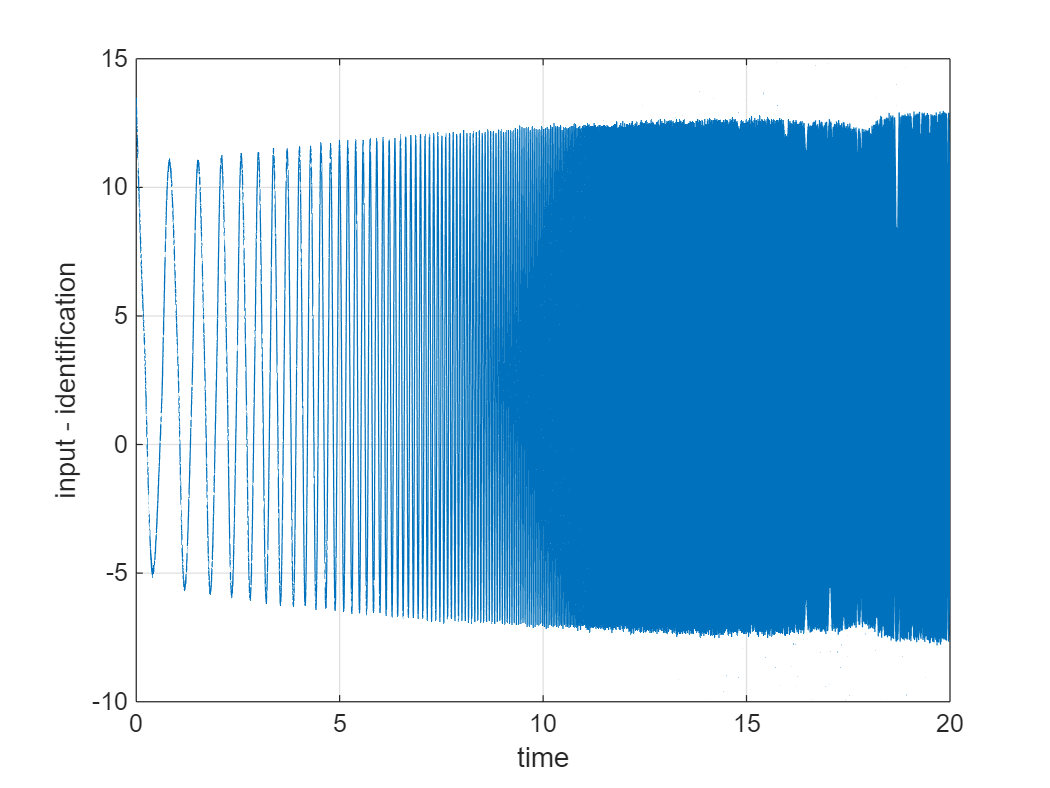

control_action=joint_torque(:,ngiunto);
figure
plot(time,control_action)
xlabel('time')
ylabel('input - identification')
grid on

Spettrogramma (contenuto frequenziale al variare del tempo)

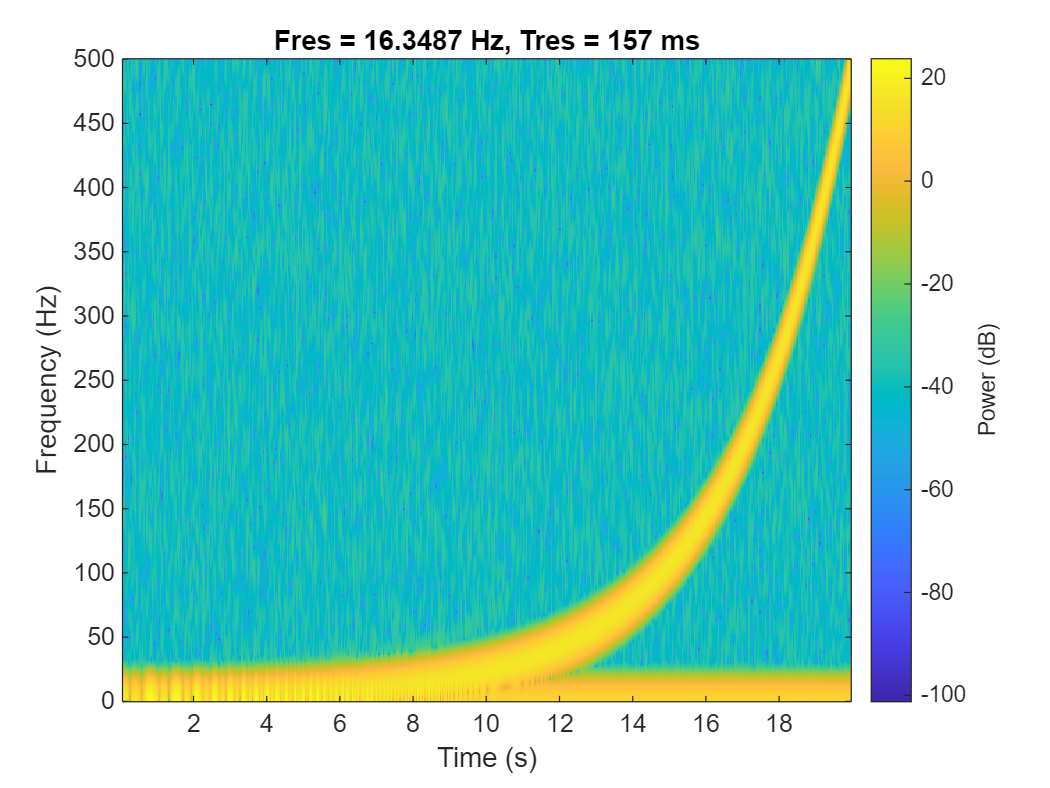

pspectrum(control_action,1/Tc,'spectrogram');

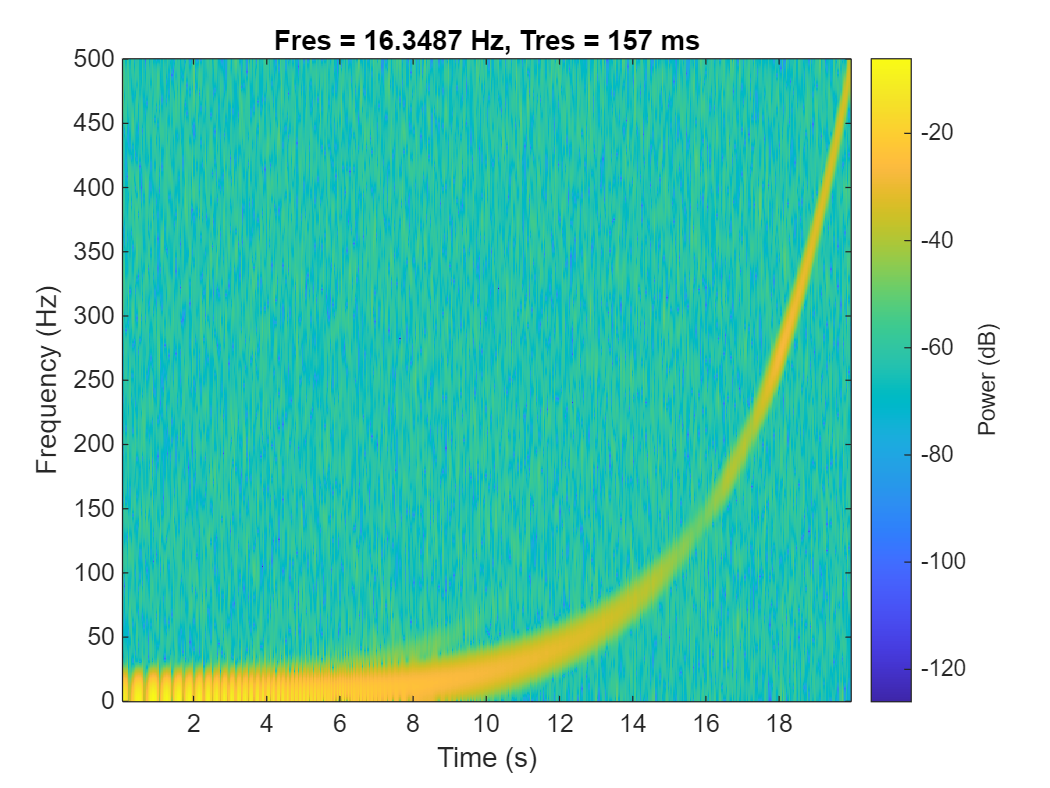


output=joint_velocity(:,ngiunto);

figure
pspectrum(output,1/Tc,'spectrogram');

## Identificazione

### Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(output,control_action,Tc);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification);

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on

plotto l'intervallo di confidenza

showConfidence(h,3)

Plotto la frequenza di inizio e fine del segnale eccitante

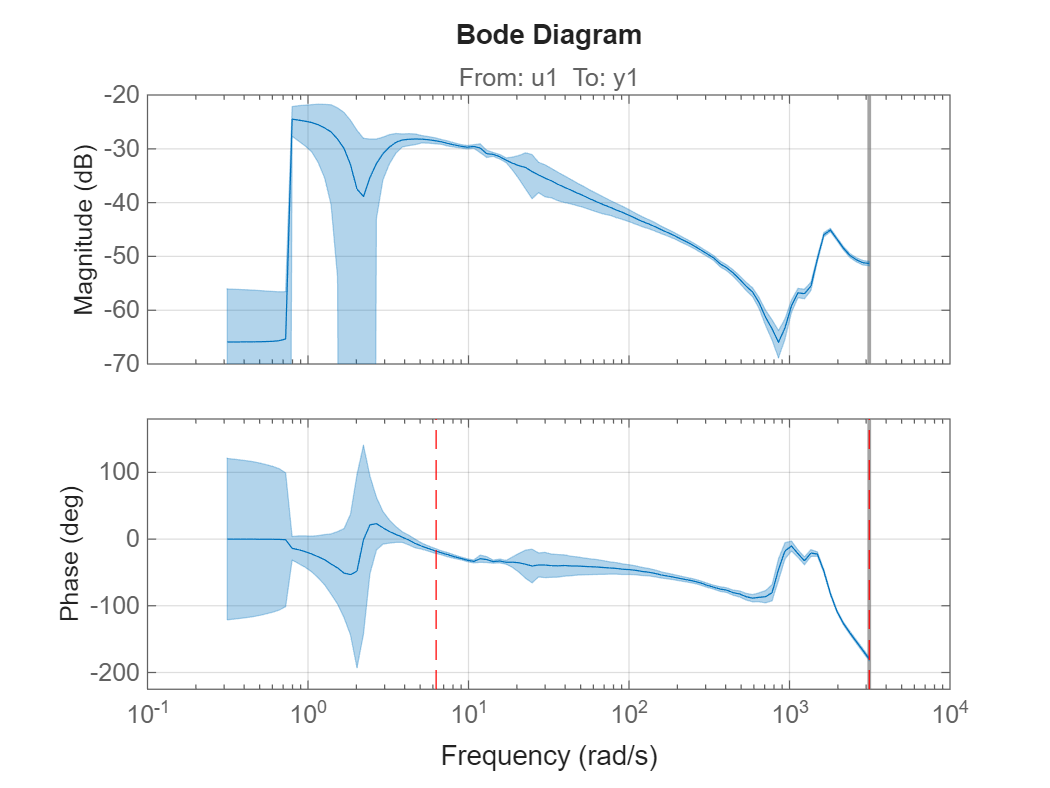


plot(w0*[1 1],ylim,'--r')
plot(w1*[1 1],ylim,'--r')
hold off

Nella parte a sinistra nella linea tratteggiata,il segnale non ha contribuito informativo apprezzabile ed è "disturbato" dalla presenza dell'attrito Coulombiano e dal controllore che compensa il disturbo.

### Stima del modello

scelgo un modello di ordine 5

ordine=5;
peso=ones(length(freq_resp_ident.Frequency),1);
wpeso0=100;
wpeso1=w1;
peso(freq_resp_ident.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident.Frequency>wpeso1)=1e-5;
 
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo = ssest(freq_resp_ident,ordine,opts);
modello_discreto = ssest(freq_resp_ident,ordine,'Ts',Tc,opts);

### Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

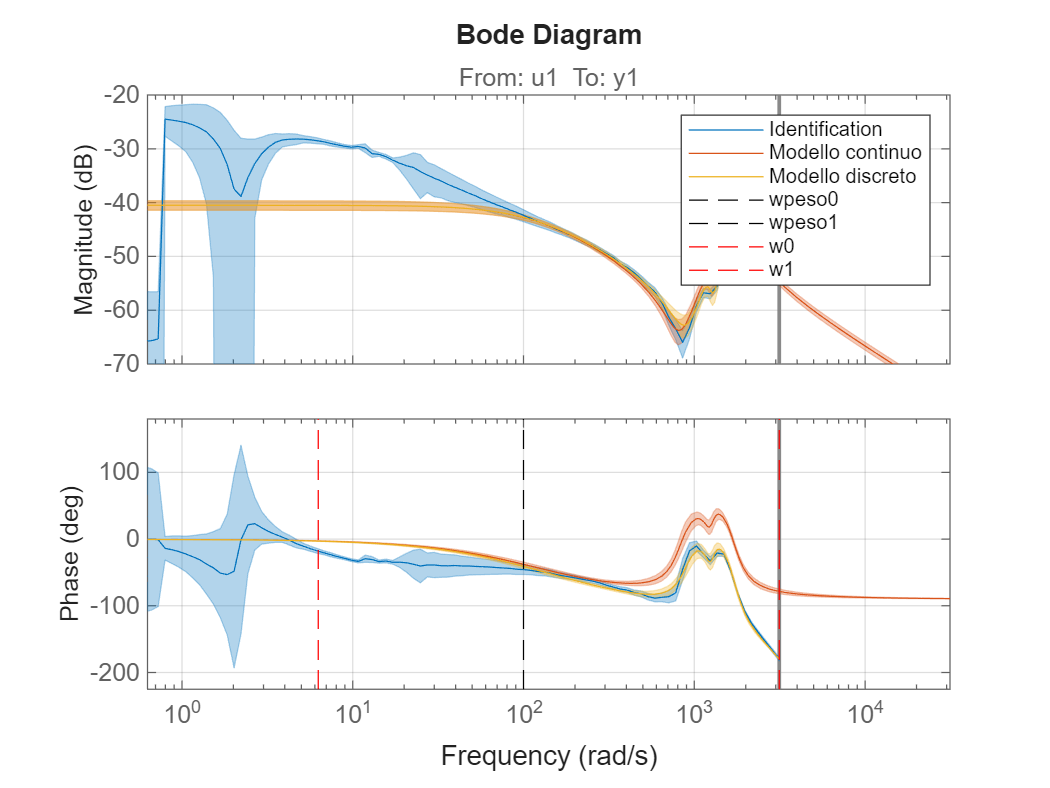

bode(modello_continuo,modello_discreto, bode_opts)
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')
plot(w0*[1 1],ylim,'--r')
plot(w1*[1 1],ylim,'--r')
hold off
grid on
xlim([.1*w0 10*w1])

legend('Identification','Modello continuo','Modello discreto','wpeso0','wpeso1','w0','w1')


save([model_name,'/modello_secondo_giunto'],'modello_continuo','modello_discreto')

Ricordiamoci di validare facendo altre prove con un segnale in ingresso diverso.